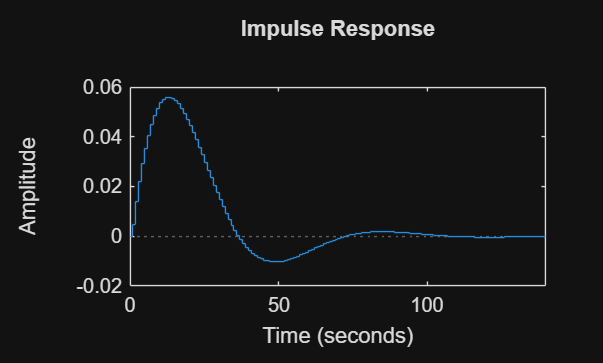

A=[-1 0;1 0];
B=[1;0];
C=[0 1];
D=0;
td = [0:1:100];

[fi,gama,C_1,D_1]=c2dm(A,B,C,D,0.1,'zoh');
[numz,denz]=ss2tf(fi,gama,C_1,D_1);
[nz,dz]=feedback(numz, denz,1,1);

[fi_1,gama_1,C_2,D_2]=tf2ss(nz,dz);

dimpulse(fi_1,gama_1,C_2,D_2)

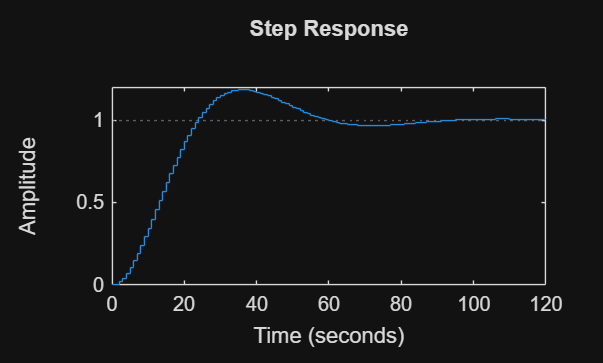

dstep(fi_1,gama_1,C_2,D_2)

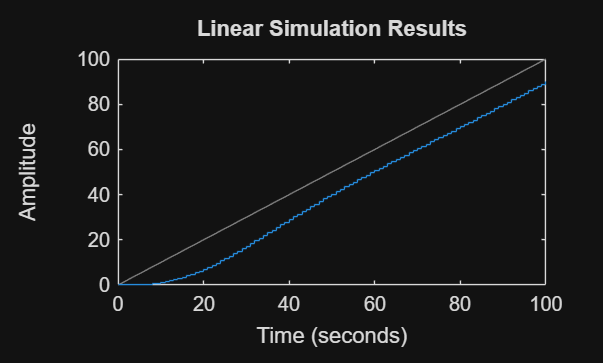

dlsim(fi_1,gama_1,C_2,D_2,td)